# 5.3 IIR 的级联型与并联型：把 H(z) 拆成二阶节；结构不同，系数舍入的后果大不相同

在 MATLAB 编辑器中打开，点击“运行”；或逐节运行。仅使用基础 MATLAB。

clearvars;
LIVE = strcmp(getenv('DSP_LIVE'), '1');
if LIVE, newpanel = @(varargin) figure('Color','w','Position',[80 80 640 420]); else, newpanel = @(varargin) nexttile(varargin{:}); end
if LIVE, set(groot, 'defaultLegendLocation', 'southoutside'); else, set(groot, 'defaultLegendLocation', 'best'); end
outdir = fullfile(fileparts(mfilename('fullpath')), 'results');
if ~exist(outdir, 'dir'), mkdir(outdir); end

## 演示1：级联型——教材例 5.3：H(z)=3(1+z^-1)(1−3.14z^-1+z^-2) / [(1−0.6z^-1)(1+0.7z^-1+0.72z^-2)]

A = 3; b1 = [1 1]; a1 = [1 -0.6]; b2 = [1 -3.14 1]; a2 = [1 0.7 0.72];
B = A*conv(b1, b2); Aa = conv(a1, a2);            % 乘开成直接型：B(z)/Aa(z)
Nh = 30; delta = [1 zeros(1, Nh-1)];
hDir = filter(B, Aa, delta);
hCas = A*filter(b2, a2, filter(b1, a1, delta));   % 第一节的输出作第二节的输入
errCas = max(abs(hCas - hDir));

## 演示2：并联型——同一个 H(z) 拆成 G0 + A1/(1−0.6z^-1) + (r0 + r1 z^-1)/(1+0.7z^-1+0.72z^-2)（教材式 (5.2.9)）

分子恒等式：B(z) = G0·Aa(z) + A1·a2(z) + (r0 + r1 z^-1)·a1(z)，比较 z^0…z^-3 的系数得 4 个线性方程

col = @(p) [p(:); zeros(4 - numel(p), 1)];
Mtx = [col(Aa), col(a2), col(conv([1 0], a1)), col(conv([0 1], a1))];
coef = Mtx \ col(B); G0 = coef(1); A1 = coef(2); r0 = coef(3); r1 = coef(4);
hPar = G0*delta + filter(A1, a1, delta) + filter([r0 r1], a2, delta);   % 各节并行，输出相加
errPar = max(abs(hPar - hDir));
p54 = max(abs(roots([1 -2.95 3.14])));           % 教材例 5.4 第一节的极点模（供课堂说明）

## 演示3：系数量化——一个极点密集的六阶系统，直接型与级联型的系数都舍入到 Bits 位小数，极点跑到哪里（教材 5.2.2 的论断）

rp = 0.98; th = [0.10 0.12 0.14]*pi;
secs = zeros(3, 3); for i = 1:3, secs(i, :) = [1 -2*rp*cos(th(i)) rp^2]; end   % 三个二阶节的分母
Ad = 1; for i = 1:3, Ad = conv(Ad, secs(i, :)); end                          % 直接型分母（六阶）
Bits = 8; q = @(c) round(c*2^Bits)/2^Bits;                                    % 舍入到 2^-Bits
AdQ = q(Ad); pDirQ = roots(AdQ);
pCasQ = zeros(6, 1); for i = 1:3, pCasQ(2*i-1:2*i) = roots(q(secs(i, :))); end
pExact = roots(Ad);
dDir = max(arrayfun(@(p) min(abs(pDirQ - p)), pExact));   % 每个精确极点到最近的量化极点的距离，取最大
dCas = max(arrayfun(@(p) min(abs(pCasQ - p)), pExact));
rDirQ = max(abs(pDirQ)); rCasQ = max(abs(pCasQ));

## 演示4：量化后的幅频响应：直接型走样，级联型几乎不变

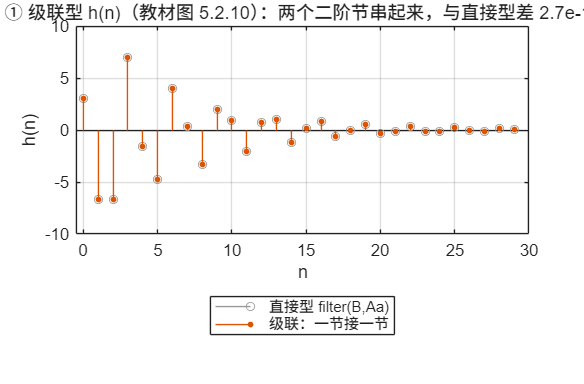

w = linspace(0, 0.5*pi, 2048);
Hex = 1 ./ dtft_resp(Ad, 1, w); Hdq = 1 ./ dtft_resp(AdQ, 1, w);
Hcq = ones(size(w)); for i = 1:3, Hcq = Hcq ./ dtft_resp(q(secs(i, :)), 1, w); end
ref = max(abs(Hex));

if ~LIVE, f1 = figure('Name','03 IIR 级联与并联','Color','w','Position',[60 40 1250 900]); end
if ~LIVE, tiledlayout(2,2,'TileSpacing','compact','Padding','compact'); end
newpanel(); stem(0:Nh-1, hDir, 'MarkerSize', 5, 'Color', [0.6 0.6 0.6]); hold on; stem(0:Nh-1, hCas, 'filled', 'MarkerSize', 3);
grid on; xlim([-0.5 Nh]); xlabel('n'); ylabel('h(n)');
title(sprintf('① 级联型 h(n)（教材图 5.2.10）：两个二阶节串起来，与直接型差 %.1e', errCas));
legend('直接型 filter(B,Aa)', '级联：一节接一节');

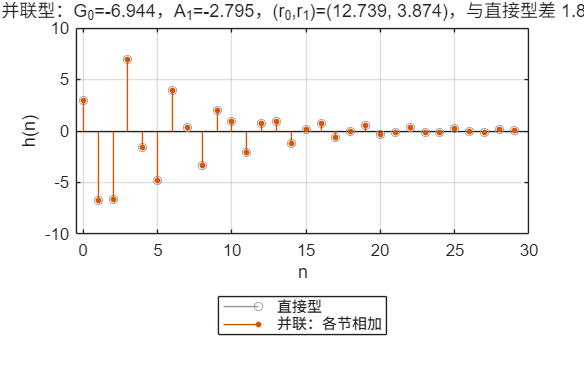

newpanel(); stem(0:Nh-1, hDir, 'MarkerSize', 5, 'Color', [0.6 0.6 0.6]); hold on; stem(0:Nh-1, hPar, 'filled', 'MarkerSize', 3);
grid on; xlim([-0.5 Nh]); xlabel('n'); ylabel('h(n)');
title(sprintf('② 并联型：G_0=%.3f，A_1=%.3f，(r_0,r_1)=(%.3f, %.3f)，与直接型差 %.1e', G0, A1, r0, r1, errPar));
legend('直接型', '并联：各节相加');

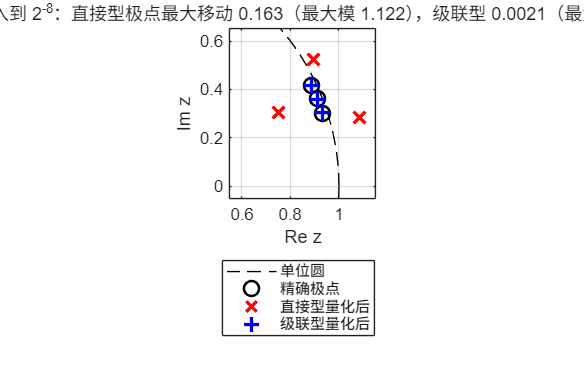

newpanel(); tt = linspace(0, 2*pi, 400); plot(cos(tt), sin(tt), 'k--'); hold on; axis equal; grid on;
plot(real(pExact), imag(pExact), 'ko', 'MarkerSize', 9, 'LineWidth', 1.5);
plot(real(pDirQ), imag(pDirQ), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
plot(real(pCasQ), imag(pCasQ), 'b+', 'MarkerSize', 10, 'LineWidth', 2);
xlim([0.55 1.15]); ylim([-0.05 0.65]); xlabel('Re z'); ylabel('Im z');
title(sprintf('③ 系数舍入到 2^{-%d}：直接型极点最大移动 %.3f（最大模 %.3f），级联型 %.4f（最大模 %.3f）', Bits, dDir, rDirQ, dCas, rCasQ));
legend('单位圆', '精确极点', '直接型量化后', '级联型量化后');

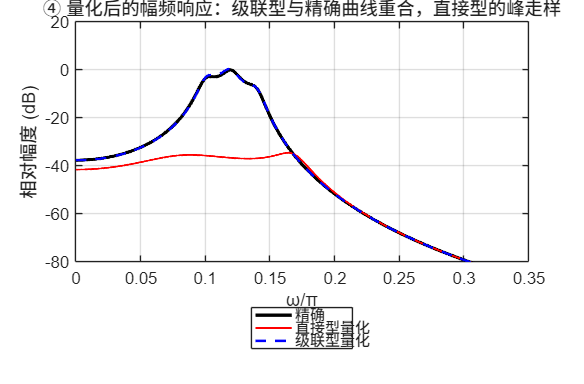

newpanel(); plot(w/pi, 20*log10(abs(Hex)/ref), 'k-', 'LineWidth', 2); hold on;
plot(w/pi, 20*log10(abs(Hdq)/ref), 'r-', 'LineWidth', 1.2); plot(w/pi, 20*log10(abs(Hcq)/ref), 'b--', 'LineWidth', 1.5);
grid on; xlabel('ω/π'); ylabel('相对幅度 (dB)'); ylim([-80 20]);
title('④ 量化后的幅频响应：级联型与精确曲线重合，直接型的峰走样');
legend('精确', '直接型量化', '级联型量化');

if ~LIVE, sgtitle('级联与并联：算出来的 h(n) 一样；系数舍入时，二阶节各管各的极点，直接型的极点互相牵连'); end
if ~LIVE, prepare_export(f1); end
if ~LIVE, exportgraphics(f1, fullfile(outdir, '03-iir-cascade-parallel.png'), 'Resolution', 150); end

## 教师核验

assert(errCas < 1e-12 && errPar < 1e-9, '级联/并联应与直接型逐点一致');
assert(max(abs(Mtx*coef - col(B))) < 1e-12, '并联系数不满足恒等式');
assert(dCas < 0.02 && dDir > 5*dCas, '量化敏感度对比不符预期');
assert(p54 > 1, '例 5.4 第一节极点应在单位圆外');
metrics = struct('matlab_version', version, 'run_at', char(datetime('now','Format','yyyy-MM-dd HH:mm:ss')), ...
    'B_direct', B, 'A_direct', Aa, 'err_cascade', errCas, 'parallel_G0', G0, 'parallel_A1', A1, 'parallel_r0', r0, 'parallel_r1', r1, 'err_parallel', errPar, ...
    'textbook_ex54_section1_pole_radius', p54, 'quant_bits', Bits, 'sixth_order_Ad', Ad, ...
    'pole_shift_direct', dDir, 'pole_shift_cascade', dCas, 'max_pole_radius_directQ', rDirQ, 'max_pole_radius_cascadeQ', rCasQ, 'all_checks_passed', true);
fid = fopen(fullfile(outdir, 'verification-iir-cascade-parallel.json'), 'w', 'n', 'UTF-8'); assert(fid >= 0);
fprintf(fid, '%s\n', jsonencode(metrics, PrettyPrint=true)); fclose(fid);
disp(metrics); fprintf('\n课堂图已保存到：%s\n', outdir);

                        matlab_version: '25.2.0.3360999 (R2025b) Update 7'
                                run_at: '2026-09-18 20:50:32'
                              B_direct: [3 -6.4200 -6.4200 3]
                              A_direct: [1 0.1000 0.3000 -0.4320]
                           err_cascade: 2.6645e-15
                           parallel_G0: -6.9444
                           parallel_A1: -2.7947
                           parallel_r0: 12.7391
                           parallel_r1: 3.8742
                          err_parallel: 1.7764e-15
    textbook_ex54_section1_pole_radius: 1.7720
                            quant_bits: 8
                        sixth_order_Ad: [1 -5.4599 12.8160 -16.5118 12.3084 -5.0360 0.8858]
                     pole_shift_direct: 0.1626
                    pole_shift_cascade: 0.0021
               max_pole_radius_directQ: 1.1218
              max_pole_radius_cascadeQ: 0.9803
                     all_checks_passed: 1


课堂图已保存到：C:\Users\Administrato

## 本地函数

function H = dtft_resp(b, a, w)
z = exp(-1i*w(:).');
H = polyval(fliplr(b), z) ./ polyval(fliplr(a), z);
end

function prepare_export(fig)
axesList = findall(fig, 'Type', 'axes');
for a = 1:numel(axesList), axesList(a).Toolbar.Visible = 'off'; end
drawnow;
end